# Second Partial Examination - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

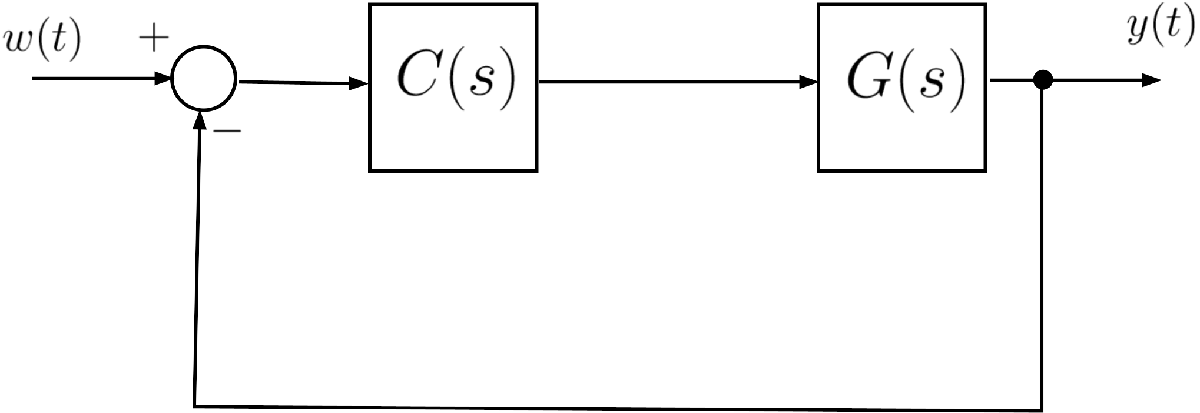	

where $G(s)$ is given by                


$$G(s) = \frac{8.25}{s\,(1+0.125\,s)\,(1+10\,s)}\;$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left| e(\infty)\right| \le 0.25$ for $w(t) = t\cdot \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function;

- $t_{s\,1\%} \le 7 \,\text{s}$  , where $t_{s\,1\%}$ is the settling time at $1\,\%$ ; 

- $\Delta \% \le 33\%$, where $\Delta \%$ is the maximum percentage overshoot, defined by 

                                        
$$\Delta \% = 100\cdot\frac{y_p-y(\infty)}{y(\infty)}$$
 

            where $y_p$ is the peak-value of the output.

**Hint**: the maximum percentage overshoot $\Delta \%$ depends on the damping factor $\xi$ of the closed-loop dominant poles (refer to Part 7 of the course material) and there is also an approximate relationship between the phase margin $\varphi_m$ and the damping factor of the closed-loop dominant poles (refer to Part 9 of the course material).

Come prima cosa, visualizzo in che situazione mi trovo data la $G(s)$ e ipotizzo di creare un controllore il più sempolice possibile per stabilizzarla.

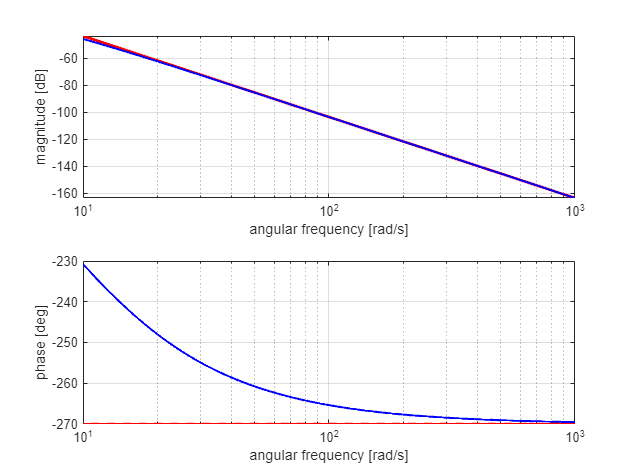

clear
addpath(genpath('BodeDiagram/'))

s=tf('s');

%scrivo Gs
Gs=8.25/(s*(1+0.125*s)*(1+10*s));

%visualizzo i grafici e inizio a ipotizzare una strategia di risoluzione semplice
Cs1 = tf(1);
Ls = Gs * Cs1;
figure;drawBodediagrams(Ls);

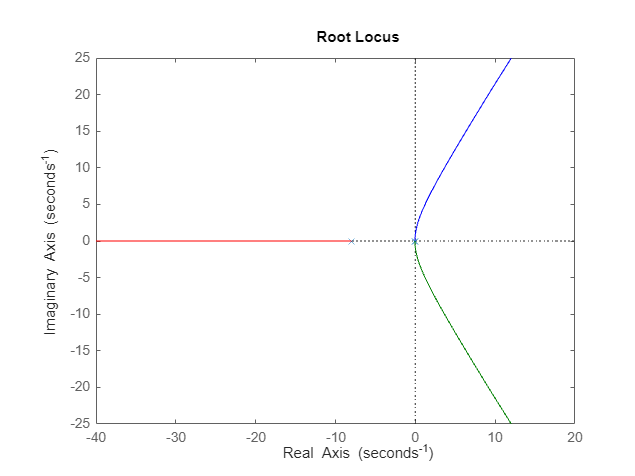

figure; rlocus(Ls);

Osservando il grafico del Root Locus, posso tentare una prima risoluzione

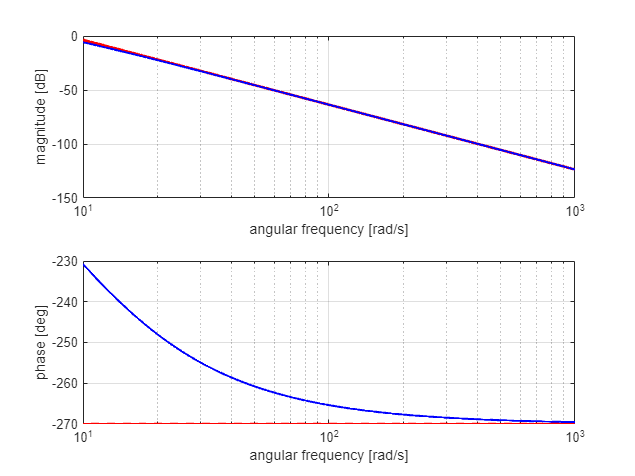

Cs1 = tf(100);
Ls = Gs * Cs1;
figure;drawBodediagrams(Ls);

figure; rlocus(Ls);

Progetto un controllore che mi elimini il polo $(1+10\text{s})$ e il polo in zero, e che compensi il grado del denominatore con due poli, cercando di limitare l'overshoot

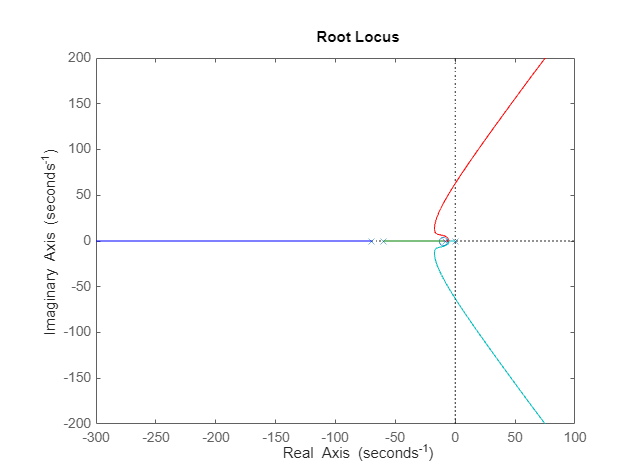

Cs1 = s*(1+0.1*s) / ((1 + s/60)*(1+s/70));
Ls = minreal(Gs*Cs1);
figure; rlocus(Ls);

In questo modo ho portato tutto a sinistra dell'asse immaginario e posso affermare che tutti i requisiti sono stati soddisfatti, anche se non sono riuscita a eliminare l'overshoot, nonostante questo è entro i parametri richiesti.

Il controllore finale è quindi

Cs = 34.659 * (s+10)*(s+0.1)/(s+20);

.Ora verifico il tutto nel designer:

controlSystemDesigner(Gs , Cs);